The pde Solution with Schnackenberg modell isn`t robust for different random starting position. For example for a = 0.2 and b = 0.5. For example the grid point of d = 47.5 and  g = 690 has different mode with different random startposition and how strong the noise is.

%%loading Rng seeds:Schnack_rng and Schnack_rng2

load("Schnack_unstable_rng_seed.mat")
S1 = Schnackenberg(0.2,0.5,47.5,690);
S1.rng_seed = Schnack_rng;
S2 = S1;
S2.rng_seed = Schnack_rng2;

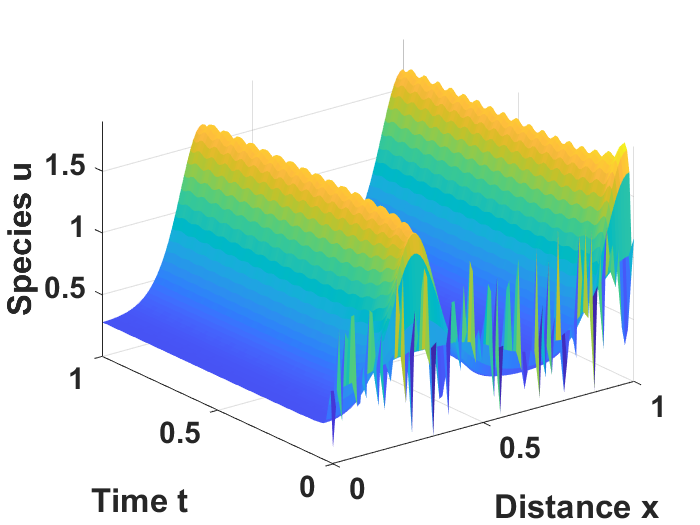

Schnackenberg_solv(S1,1e-0,'Plot_display',1);

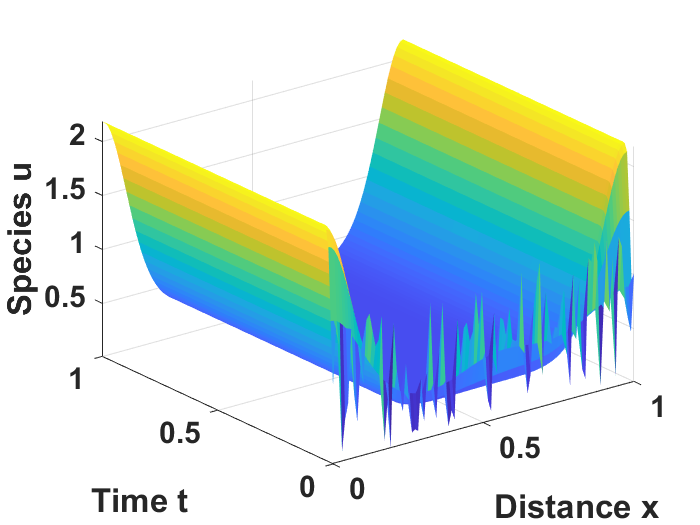

u1_rng2 = Schnackenberg_solv(S2,1e-0,'Plot_display',1);

Schnackenberg solution is changing for different rng_seed even the mode

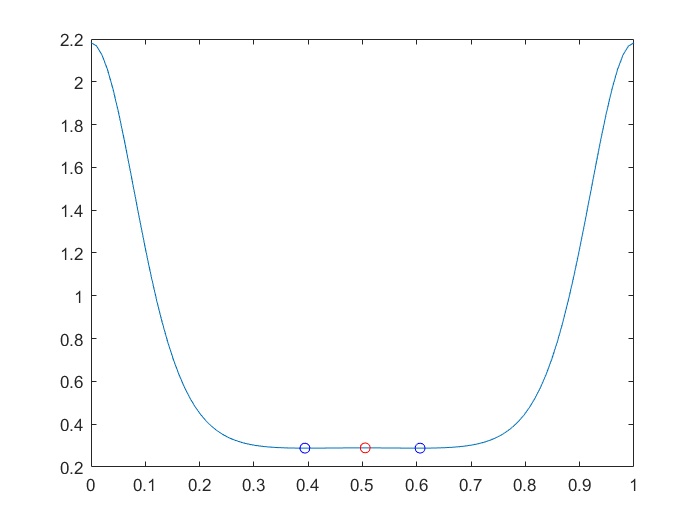

rng2_max = islocalmax(u1_rng2(end,:));
rng2_min = islocalmin(u1_rng2(end,:));
figure;
plot(S2.xspan,u1_rng2(end,:))
hold on

plot(S2.xspan(rng2_max),u1_rng2(end,rng2_max),'ro')
plot(S2.xspan(rng2_min),u1_rng2(end,rng2_min),'bo')

hold off

With numeric we find out that we have 3 local extremas.

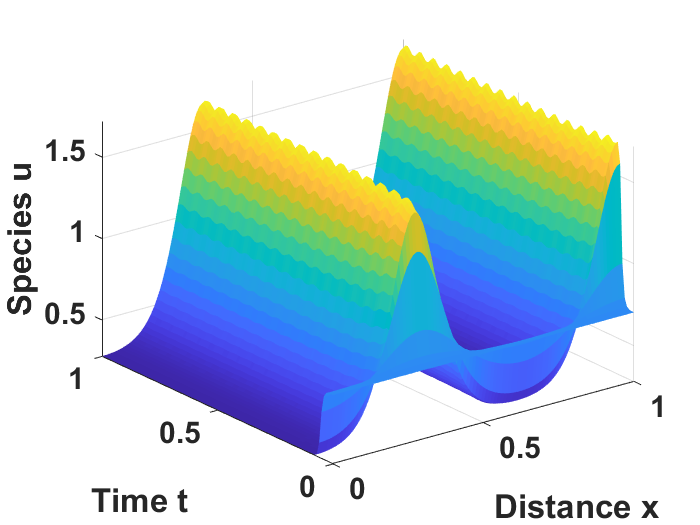

Schnackenberg_solv(S1,1e-3,'Plot_display',1);

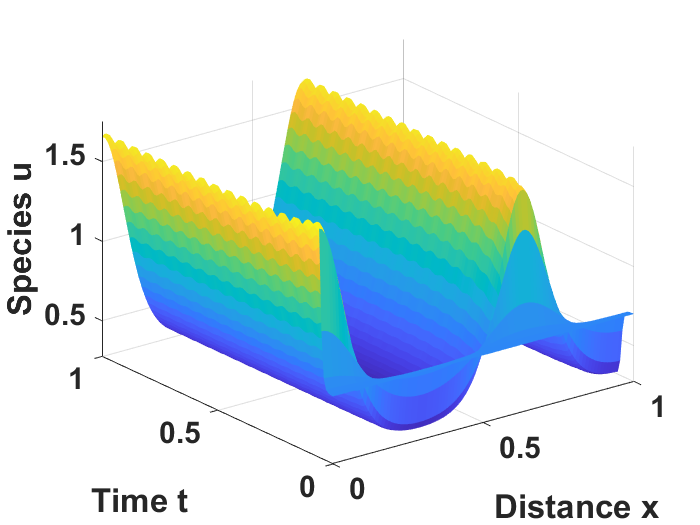

Schnackenberg_solv(S2,1e-3,'Plot_display',1);

Changing the amplitude of the noise changes the turing pattern also.

S1_temp = Schnackenberg_solv(S1,1e-4,'Plot_display',1);
[S2_temp,~,tspan] = Schnackenberg_solv(S2,1e-4,'Plot_display',1);
gif_sol_time(S1_temp,tspan)
gif_sol_time(S2_temp,tspan)

The Solution isn´t sometimes in an stabel Turingpattern state. So for S2 if simulate for t = 0,1 we get only one maximum but if we simulate for t = 0,3 we get completly other patterns. But for S1 nothing change

The S2 patterns  are getting smaller and have mode 5.

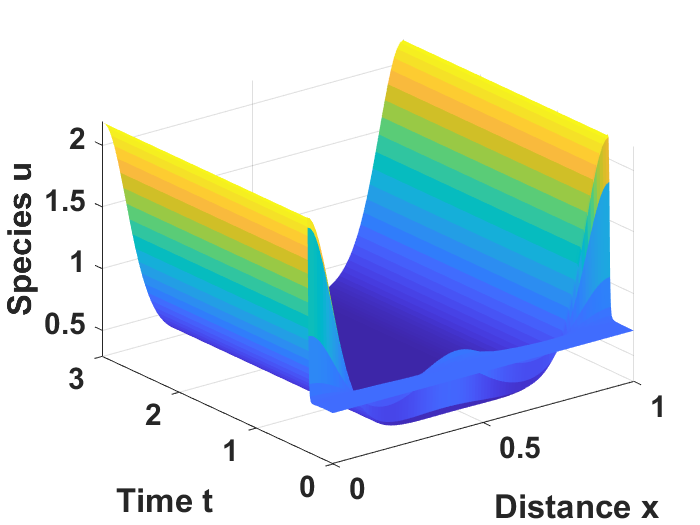

Schnackenberg_solv(S1,1e-4,3,'Plot_display',1);

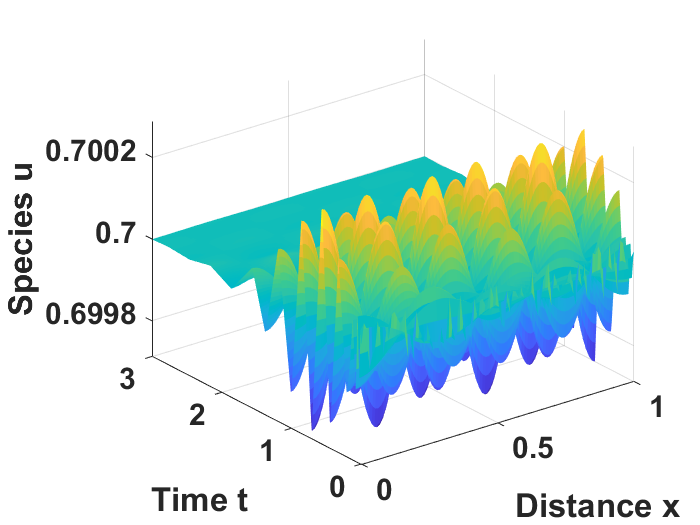

[S2_temp,~,tspan] = Schnackenberg_solv(S2,1e-4,3,'Plot_display',1);

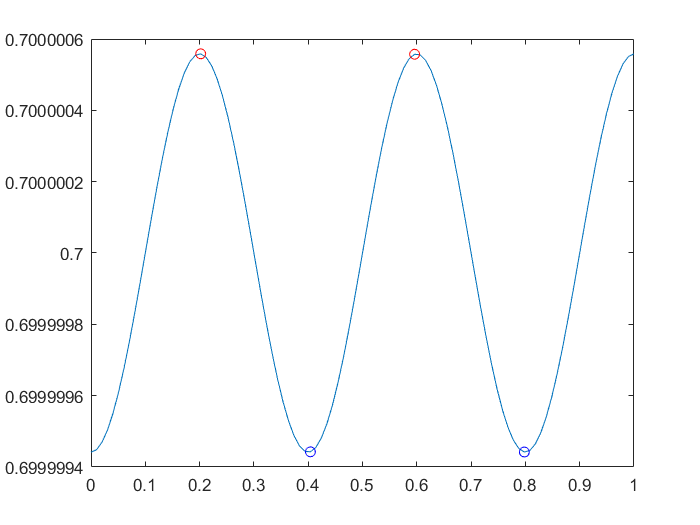

gif_sol_time(S2_temp,tspan) 

Looking the at the evolution in time pdepe the mode of the pattern isnt changning after 1.5s.

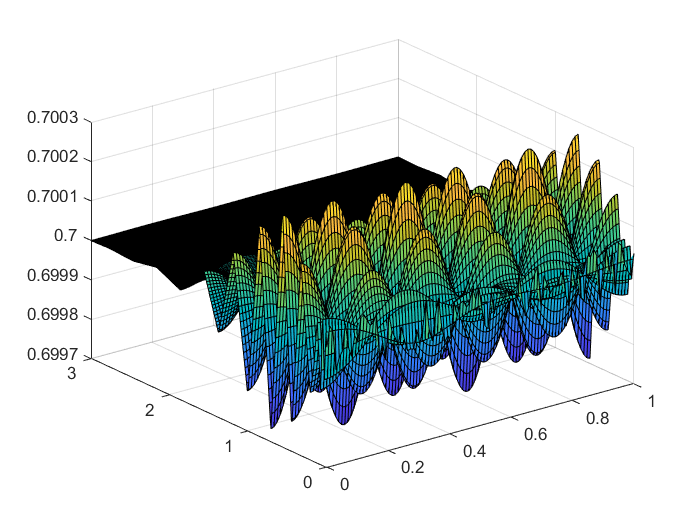

j_t = linspace(0.8,3,20);
[S2_jt,~,S2_jt_end] = Schnackenberg_t_change(S2,j_t,1e-4);

gif_sol_surv(S2_jt,j_t,'change_t',true)

S2_jt_mode = Mode_test(S2_jt_end,'MinProminence',0.01);

Unrecognized function or variable 'Mode_test'.

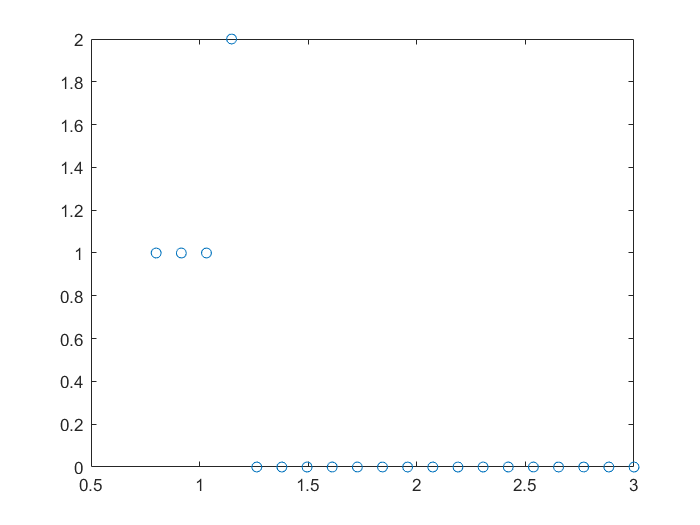

plot(j_t,S2_jt_mode,'o');

Looking at the evolution in amplitude noise with different timespace maxt = 1,3,5

j_noise = logspace(-10,-3,20);

S1.maxt = 1;
S1tspan1 = S1.tspan;
[S1_jnoise1,~,S1_jnoise_end1] = Schnackenberg_change(S1,'noise',j_noise);

S1.maxt = 3;
S1tspan3 = S1.tspan;
[S1_jnoise3,~,S1_jnoise_end3] = Schnackenberg_change(S1,'noise',j_noise);

S1.maxt = 5;
S1tspan5 = S1.tspan;
[S1_jnoise5,~,S1_jnoise_end5] = Schnackenberg_change(S1,'noise',j_noise);

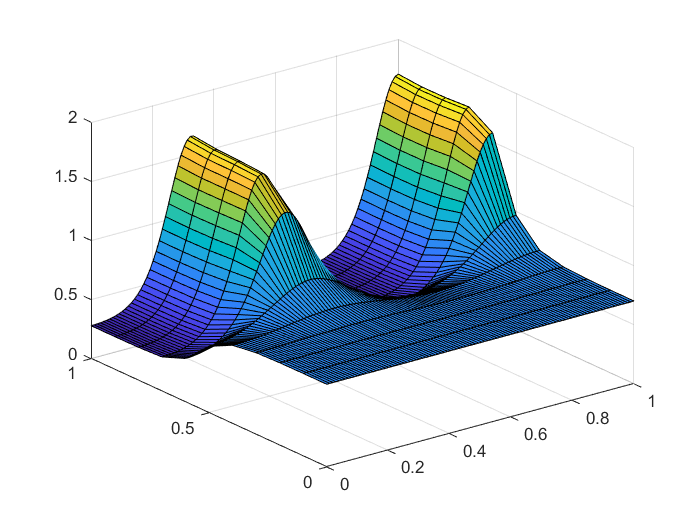

gif_sol_surv(S1_jnoise1,S1tspan1);

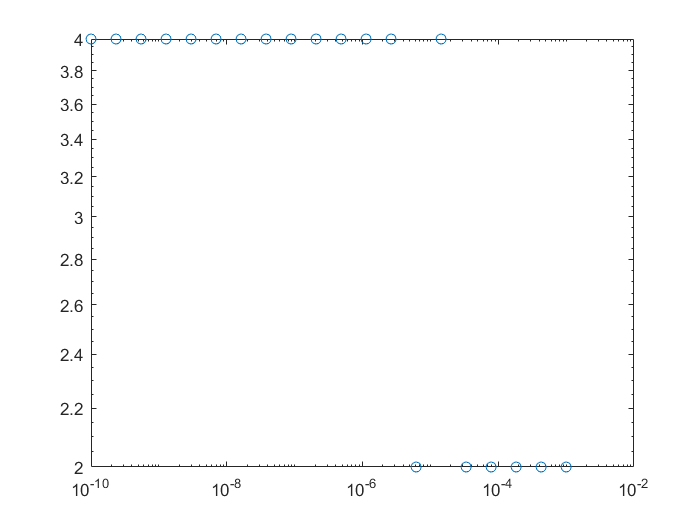

S1_jnoise_mode = Mode_test(S1_jnoise_end1,'MinProminence',0);
figure;
loglog(j_noise,S1_jnoise_mode,'o');

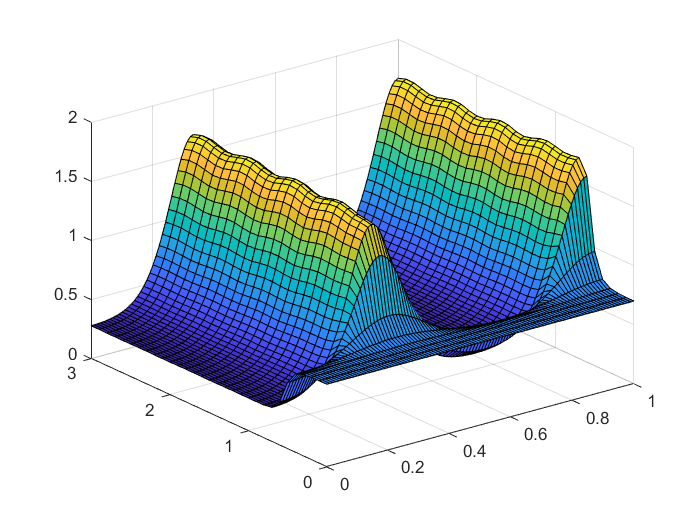


gif_sol_surv(S1_jnoise3,S1tspan3);

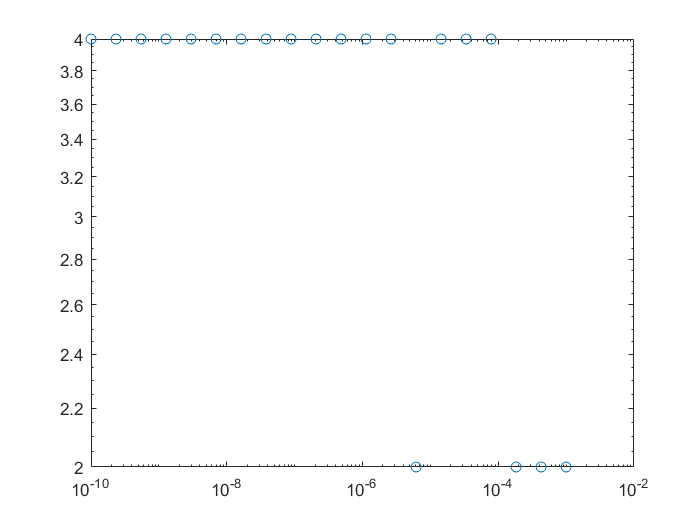

S1_jnoise_mode3 = Mode_test(S1_jnoise_end3,'MinProminence',0);
figure;
loglog(j_noise,S1_jnoise_mode3,'o');

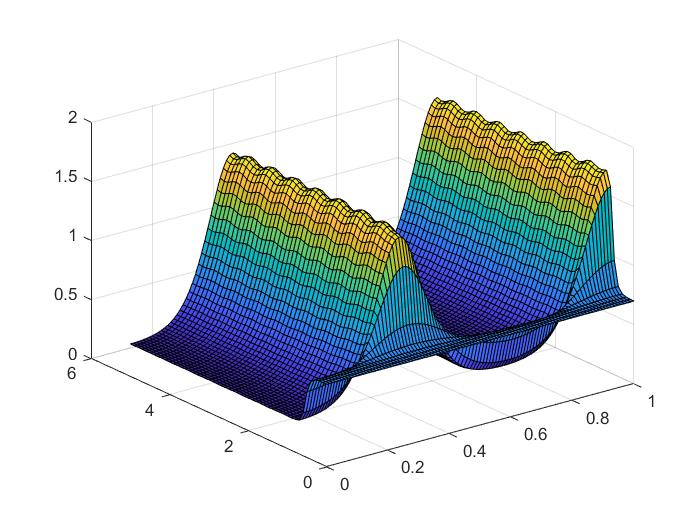


gif_sol_surv(S1_jnoise5,S1tspan5);

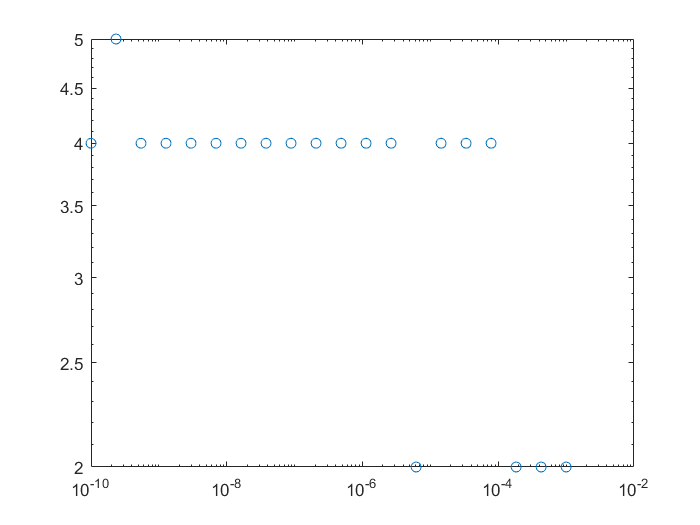

S1_jnoise_mode5 = Mode_test(S1_jnoise_end5,'MinProminence',0);
figure;
loglog(j_noise,S1_jnoise_mode5,'o');

Same analyse with S2

j_noise = logspace(-10,-3,20);

S2.maxt = 1;
S2tspan1 = S2.tspan;
[S2_jnoise1,~,S2_jnoise_end1] = Schnackenberg_change(S2,'noise',j_noise);

S2.maxt = 3;
S2tspan3 = S2.tspan;
[S2_jnoise3,~,S2_jnoise_end3] = Schnackenberg_change(S2,'noise',j_noise);

S2.maxt = 5;
S2tspan5 = S2.tspan;
[S2_jnoise5,~,S2_jnoise_end5] = Schnackenberg_change(S2,'noise',j_noise);

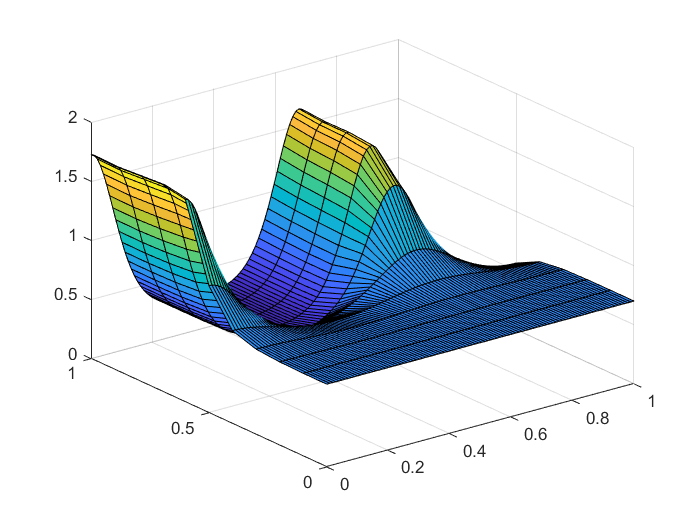

gif_sol_surv(S2_jnoise1,S2tspan1);

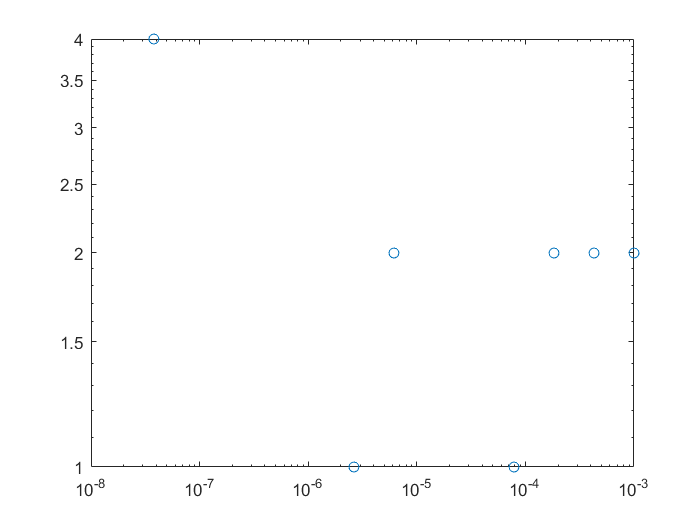

S2_jnoise_mode = Mode_test(S2_jnoise_end1,'MinProminence',0.01);
figure;
loglog(j_noise,S2_jnoise_mode,'o');

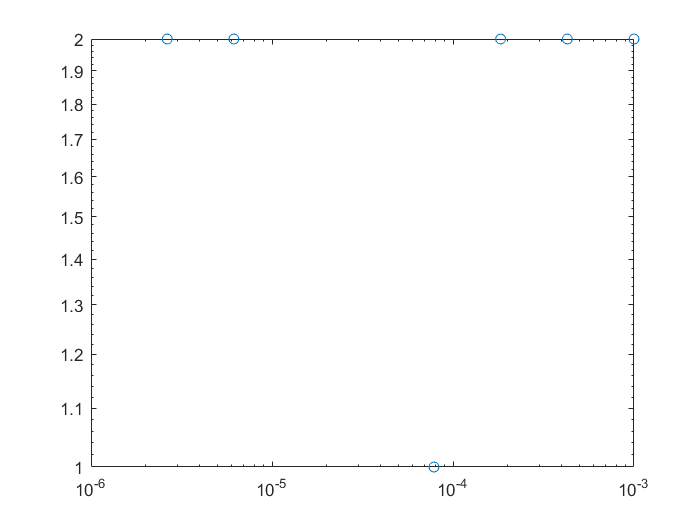


%gif_sol_surv(S2_jnoise3,S2tspan3);
S2_jnoise_mode3 = Mode_test(S2_jnoise_end3,'MinProminence',0.01);
figure;
loglog(j_noise,S2_jnoise_mode3,'o');


%gif_sol_surv(S2_jnoise5,S2tspan5);
S2_jnoise_mode5 = Mode_test(S2_jnoise_end5,'MinProminence',0.01);
figure;
loglog(j_noise,S2_jnoise_mode5,'o');